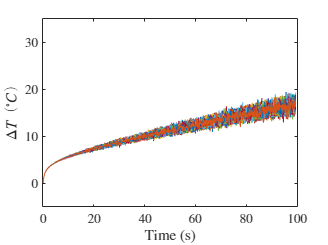

clear
Nx = 1e3;
Ns = 100;
x = linspace(0,100, Nx);
x(1) = [];
y = zeros(Ns,length(x));
for ii = 1:Ns
    rMean = x / 10;
    rStd = rMean/12;
    y(ii,:) = log(x) + random("Normal", rMean, rStd, size(x));
    y(ii,:) = y(ii,:) - min(y(ii,:));
end

for ii = size(y,2):-1:1
    y_err(ii) = fitdist(y(:,ii), "Normal");
end

figure
plot(x, y)
ax = gca;
ax.Box = "on";
ax.ClippingStyle = "rectangle";
ax.TickLabelInterpreter = "latex";
xlabel("Time (s)", Interpreter="latex")
ylabel("$$\Delta T \ (^{\circ}C)$$", Interpreter="latex")
ax.YLim = [-5 35];

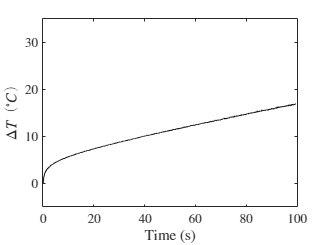


figure
plot(x,[y_err.mu], "k")
ax = gca;
ax.Box = "on";
ax.ClippingStyle = "rectangle";
ax.TickLabelInterpreter = "latex";
xlabel("Time (s)", Interpreter="latex")
ylabel("$$\Delta T \ (^{\circ}C)$$", Interpreter="latex")
ax.YLim = [-5 35];

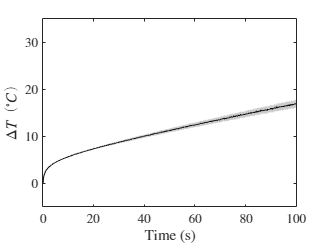


figure
boundedline(x, [y_err.mu], [y_err.sigma],'-k')
ax = gca;
ax.Box = "on";
ax.ClippingStyle = "rectangle";
xlabel("Time (s)", Interpreter="latex")
ylabel("$$\Delta T \ (^{\circ}C)$$", Interpreter="latex")
ax.TickLabelInterpreter = "latex";
ax.YLim = [-5 35];

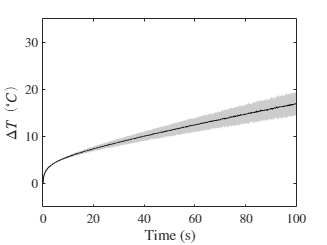


figure
boundedline(x, [y_err.mu], [y_err.sigma]*3,'-k')
ax = gca;
ax.Box = "on";
ax.ClippingStyle = "rectangle";
xlabel("Time (s)", Interpreter="latex")
ylabel("$$\Delta T \ (^{\circ}C)$$", Interpreter="latex")
ax.TickLabelInterpreter = "latex";
ax.YLim = [-5 35];

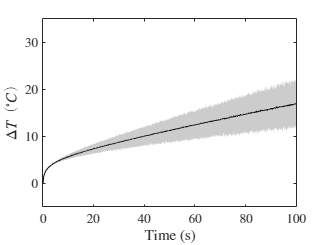


figure
boundedline(x, [y_err.mu], [y_err.sigma]*6,'-k')
ax = gca;
ax.Box = "on";
ax.ClippingStyle = "rectangle";
xlabel("Time (s)", Interpreter="latex")
ylabel("$$\Delta T \ (^{\circ}C)$$", Interpreter="latex")
ax.TickLabelInterpreter = "latex";
ax.YLim = [-5 35];